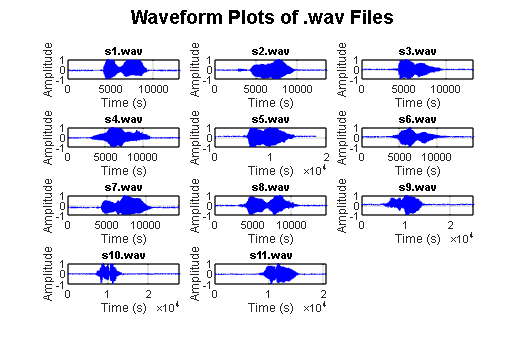

%%2O MS

% Get all .wav files in the directory
files = dir(fullfile('Training_Data', '*.wav'));

% Extract numeric values from filenames for correct sorting
fileNames = {files.name};
numValues = zeros(length(fileNames), 1);

for i = 1:length(fileNames)
    numStr = regexp(fileNames{i}, '\d+', 'match'); % Extract numeric part
    numValues(i) = str2double(numStr{1}); % Convert to number
end

% Sort files numerically
[~, sortedIdx] = sort(numValues);
files = files(sortedIdx); % Reorder file structure

% Number of files
numFiles = length(files);

% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure

for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    %normalize signal
    signal = normalize(signal, 'range', [-1,1]); 
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Select subplot position
    subplot(rows, cols, i);
    plot(signal, 'b'); % Force a consistent color (blue)
    
    % Formatting each subplot
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end

% Adjust figure layout
sgtitle('Waveform Plots of .wav Files', 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

window = 256

window = 256

overlap = window - (window/3);
nfft = 256

nfft = 256

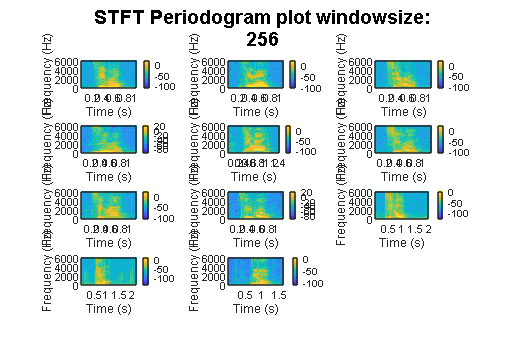



% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure


for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
 

    % Read the audio file and plot the stft
    [signal, fs] = audioread(filename);
 

    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
   

    %do stft 
    [s,f,t] = stft(signal, fs, 'Window', hamming(window), 'OverlapLength', round(overlap), 'FFTLength', nfft);
    
    % Select only positive frequencies
    positiveFreqIdx = f >= 0; 
    
    subplot(rows, cols, i);
    %imagesc(t, f(positiveFreqIdx), real(s(positiveFreqIdx, :)));
    imagesc(t, f(positiveFreqIdx), 20*log10(abs(s(positiveFreqIdx, :)) + eps));

    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    colorbar;


end

% Adjust figure layout
sgtitle(['STFT Periodogram plot windowsize:', string(window)], 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

fs = 12500;       % Sampling frequency (Hz)
nfft = 512;       % FFT size
k = 20;  % Number of Mel filters

% Generate Mel filter bank (requires Voicebox Toolbox)
melfb = melbankm(k, nfft, fs, 0, 0.5, 'm'); 

Unrecognized function or variable 'melbankm'.


% Frequency axiss in Hz
freqs = linspace(0, fs/2, nfft/2+1); 

% Plot Mel filter bank response
figure;
plot(freqs, melfb');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Mel-spaced filterbank');
grid on;


set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout
